# Gabriel Colangelo

clear
close all
clc


## Problem 4a)

Find: $|\Delta \bar{v}|_{total}, |\Delta \bar{v}|_{dep}, |\Delta \bar{v}|_{arr}$ and TOF for Hohmann transfer from Earth to Pluto, assuming coplanar circular orbit, accounting for local gravity fields.

% Earth parameters
mu_earth             = 398600.4415;
R_earth              = 6378.1363;

% Pluto parameters
mu_pluto             = 981.600887707;
R_pluto              = 1162;

% Circular orbit radius from Sun to Earth - assumed to be semi major axis of orbit 
r_sun_earth          = 149597898;   

% Circular orbit radius from Sun to Pluto - assumed to be semi major axis of orbit 
r_sun_pluto          = 5907150229; 

% Sun gravitional parameter
mu_sun               = 132712440017.99;

% Earth circular parking orbit altitude
alt_park_earth       = 250;

% Earth circular parking orbit radius
r_park_earth         = R_earth + alt_park_earth;

% Spacecraft circular parking orbit velocity relative to earth
v_earth_sc_minus     = sqrt(mu_earth/r_park_earth);

% Heliocentric Velocity of Earth - assume circular orbit
v_sun_earth         = sqrt(mu_sun/r_sun_earth);

% Periapsis of transfer ellipse
rp_T                = r_sun_earth; 

% Apoapsis of transfer ellipse
ra_T                = r_sun_pluto; 

% Semi major axis of transfer ellipse
a_T                 = (rp_T + ra_T)/2;

% Heliocentric velocity on hohmann transfer ellipse (periapsis)
vp                  = sqrt(2*(mu_sun/rp_T - mu_sun/(2*a_T)));

% Calculate excess velocity, relative to Earth
v_inf_earth         = vp - v_sun_earth;

% Calculate hyperbolic orbit energy
energy_hyp_earth    = v_inf_earth^2/2;

% Calculate s/c velocity relative to earth post maneuver on hyperbola
v_earth_sc_plus     = sqrt(2*(energy_hyp_earth + mu_earth/r_park_earth));

% Departure deltaV - subtract vectors, along same direction treat as scalar
dv_dep              = v_earth_sc_plus - v_earth_sc_minus;
fprintf('The depature deltaV is %.3f km/s',dv_dep)

The depature deltaV is 8.365 km/s


$$a_T = (r_{a_T} + r_{p_T})/2 \\
v_{earth} = \sqrt{\frac{\mu_{sun}}{r_{earth}}} = 29.78 \ [km/s] \ \text{ - 
 Heliocentric Circular Orbit Velocity of Earth}\\
v_p = \sqrt{2(\frac{\mu_{sun}}{r_{p_T}} - \frac{\mu_{sun}}{2 a_T})} = 41.6 \ [km/s]  \ \text{ - Heliocentric Velocity of s/c on transfer ellipse at periapsis}\\
\bar{v}_\infty = \bar{v}_p - \bar{v}_{earth}  \ \text{ - Earth Relative Excess Velocity of s/c} \\
\epsilon_{earth} = \frac{v_\infty^2}{2}  \ \text{Hyperbolic Orbit Energy}\\
v^+_{sc/earth} =  \sqrt{2(\epsilon_{earth} + \frac{\mu_{earth}}{r_{park}})} = 16.12 \ [km/s]  \text{ - Hyperbolic orbit velocity of s/c w.r.t Earth at maneuver point} \\
v^-_{sc/earth} = \sqrt{\frac{\mu_{earth}}{r_{park}}}  = 7.75 \ [km/s]\ \text{ - Circular Orbit Velocity of s/c w.r.t Earth} \\
\Delta \bar{v}_{dep} = \bar{v}^+_{sc/earth} - \bar{v}^-_{sc/earth}\\
\\

|\Delta \bar{v}_{dep} | = 8.365 \ [km/s]$$


$\alpha = 0$**, no change in direction during manuever, applied tangentially at periapsis.**

% Heliocentric velocity on hohmann transfer ellipse (periapsis)
va                  = sqrt(2*(mu_sun/ra_T - mu_sun/(2*a_T)));

% Final circular orbit radius
r_final_pluto       = 11*R_pluto;

% Heliocentric Velocity of pluto - assume circular orbit
v_sun_pluto         = sqrt(mu_sun/r_sun_pluto);

% Calculate excess velocity, relative to pluto
v_inf_pluto         = va - v_sun_pluto;

% Spacecraft final circular orbit velocity relative to pluto
v_pluto_sc_plus    = sqrt(mu_pluto/r_final_pluto);

% Calculate hyperbolic orbit energy
energy_hyp_pluto    = v_inf_pluto^2/2;

% Calculate s/c velocity relative to pluto pre maneuver on hyperbola
v_pluto_sc_minus    = sqrt(2*(energy_hyp_pluto + mu_pluto/r_final_pluto));

% Arrival deltaV - subtract vectors, along same direction treat as scalar
dv_arr              = v_pluto_sc_plus - v_pluto_sc_minus;
fprintf('The arrival deltaV is %.3f km/s',abs(dv_arr))

The arrival deltaV is 3.430 km/s


$$v_{pluto} = \sqrt{\frac{\mu_{sun}}{r_{pluto}}} = 4.74 \ [km/s] \ \text{ - 
 Heliocentric Circular Orbit Velocity of Pluto}\\
v_a = \sqrt{2(\frac{\mu_{sun}}{r_{a_T}} - \frac{\mu_{sun}}{2 a_T})} = 1.05 \ [km/s]  \ \text{ - Heliocentric Velocity of s/c on transfer ellipse at apoapsis}\\
\bar{v}_\infty = \bar{v}_a - \bar{v}_{pluto}  \ \text{ - Pluto Relative Excess Velocity of s/c} \\
\epsilon_{pluto} = \frac{v_\infty^2}{2}  \ \text{Hyperbolic Orbit Energy}\\
v^-_{sc/pluto} =  \sqrt{2(\epsilon_{pluto} + \frac{\mu_{pluto}}{r_{final}})} = 3.707 \ [km/s]  \text{ - Hyperbolic orbit velocity of s/c w.r.t Pluto at maneuver point} \\
v^+_{sc/pluto} = \sqrt{\frac{\mu_{Pluto}}{r_{final}}}  = 0.277 \ [km/s]\ \text{ - Circular Orbit Velocity of s/c w.r.t Pluto} \\
\Delta \bar{v}_{arr} = \bar{v}^+_{sc/pluto} - \bar{v}^-_{sc/pluto}\\
\\

|\Delta \bar{v}_{arr} | = 3.43 \ [km/s]$$


$\alpha = 180$, **applied in direction opposite of **$\bar{v}^-$**.**

% Total deltaV          
dv                   = dv_dep + abs(dv_arr);
fprintf('The deltaV magnitude for the hohmann transfer is %.3f km/s',dv)

The deltaV magnitude for the hohmann transfer is 11.795 km/s


$$|\Delta \bar{v}|_{total} =  |\Delta \bar{v}_{arr}|  + |\Delta \bar{v}_{dep}|  \\
|\Delta \bar{v}|_{total} = 11.795 \ [km/s]$$


% Period of transfer orbit
period_T            = 2*pi*sqrt(a_T^3/mu_sun);

% Time of flight for hohmann transfer - Julian years
TOF                 = (period_T/2);
fprintf('The time of flight is %.3f Julian years',TOF/(86400 * 365.25))

The time of flight is 45.541 Julian years


$$Period= 2\pi \sqrt{\frac{a^3}{\mu}} \\
T.O.F = Period /2 \\
\\
T.O.F. = 45.54 \ [\text{Julian Years}]

$$


**From PS7 problem 3, the **$|\Delta \bar{v}_{dep}| = 11.81$** and **$|\Delta \bar{v}_{arr}| = 3.69$** which combined for a **$|\Delta \bar{v}_{total}| = 15.50$**. When accounting for local gravity fields, these vaues decrease to **$|\Delta \bar{v}_{dep}| = 8.365$, $|\Delta \bar{v}_{arr}| = 3.43$,** and **$|\Delta \bar{v}_{total}| = 11.795$**. Including the local gravity fields decreased the maneuver costs at both Earth and Pluto, thereby lowering the total maneuever cost by almost 24%. The time of flight however remain unchanged, as the transfer ellipse is the same between both problems.**

## Problem 4b)

Find: $|\Delta \bar{v}|_{total}, |\Delta \bar{v}|_{arr}$ for Hohmann transfer from Earth to Pluto with elliptical capture orbit

% Pluto capture orbit properties
rp_capture          = 11*R_pluto;
e_capture           = 0.9;

% Pluto capture orbit semi major axis
a_capture           = rp_capture/(1 - e_capture);

% Pluto capture orbit energy
energy_capture      = -mu_pluto/(2*a_capture);

% Calculate s/c velocity relative to pluto pre maneuver on hyperbola
v_pluto_sc_minus_b  = sqrt(2*(energy_hyp_pluto + mu_pluto/rp_capture));

% Spacecraft capture orbit velocity relative to pluto at periapsis
v_pluto_sc_plus_b   = sqrt(2*(energy_capture + mu_pluto/rp_capture));

% Arrival deltaV - subtract vectors, along same direction treat as scalar
dv_arr_b            = v_pluto_sc_plus_b - v_pluto_sc_minus_b;
fprintf('The arrival deltaV is %.3f km/s',abs(dv_arr_b))

The arrival deltaV is 3.325 km/s


$$a_{capture} = \frac{r_{p,capture}}{1 - e_{capture}} \\
\epsilon_{capture} = \frac{-\mu}{2 a_{capture}} \\
v^-_{sc/pluto} =  \sqrt{2(\epsilon_{pluto} + \frac{\mu_{pluto}}{r_{p,capture}})} = 3.707 \ [km/s]  \text{ - Hyperbolic orbit velocity of s/c w.r.t Pluto at maneuver point} \\
v^+_{sc/pluto} =  \sqrt{2(\epsilon_{capture} + \frac{\mu_{pluto}}{r_{p,capture}})} = 0.382 \ [km/s]  \text{ - Capture orbit velocity of s/c w.r.t Pluto at maneuver point} \\
\Delta \bar{v}_{arr} = \bar{v}^+_{sc/pluto} - \bar{v}^-_{sc/pluto}\\
\\

|\Delta \bar{v}_{arr} | = 3.325 \ [km/s]$$


$\alpha = 180$, **applied in direction opposite of **$\bar{v}^-$**.**

% Total deltaV          
dv_b                 = dv_dep + abs(dv_arr_b);
fprintf('The deltaV magnitude for the hohmann transfer is %.3f km/s',dv_b)

The deltaV magnitude for the hohmann transfer is 11.690 km/s


$$|\Delta \bar{v}|_{total} =  |\Delta \bar{v}_{arr}|  + |\Delta \bar{v}_{dep}|  \\
|\Delta \bar{v}|_{total} = 11.69 \ [km/s]$$


**The elliptic transfer orbit causes a decrease in the cost of  **$|\Delta \bar{v}_{arr}|$** by 0.105 km/s, and therefore drops **$|\Delta \bar{v}_{total}|$** by the same amount. This difference occurs because the spacecraft will travel faster at the periapsis of the ellipitcal orbit, than in a circular orbit with a radius equal to that of the periapsis of the ellipitical orbit. Because the spacecraft has a higher speed, it is closer to the speed of the spacecraft on the hyperbola, therefore decreasing the required maneuver cost. With this knowledge, we know it is more efficient to to enter an eccentric orbit at periapsis rather apoapsis because the spacecraft travels with a higher speed at periapsis. The slowest part of the orbit is at apoapsis, which will increase the maneuver cost.**

## Problem 4c) Dark Side Flyby


$$\underline{Find}: r^+, v^+, \gamma^+, \theta^{*+}, a,e,r_p,r_a, period, energy, \Delta \omega$$
 

% Semi-major axis of hyperbolic orbit
a_abs           = mu_pluto/(2*energy_hyp_pluto);

% Eccentricity of hyperbolic orbit
e_H             = r_final_pluto/a_abs + 1;

% Flyby angle
delta           = 2*asind(1/e_H);

% Heliocentric velocity post flyby
v_plus_flyby    = sqrt(v_inf_pluto^2 + v_sun_pluto^2 - 2*abs(v_inf_pluto)*v_sun_pluto*cosd(delta));
fprintf('The heliocentric velocity post flyby is %.3f km/s',v_plus_flyby)

The heliocentric velocity post flyby is 1.055 km/s


$$|a| = \frac{\mu_{pluto}}{2\epsilon_{pluto}\\
e = \frac{r_p}{|a|} + 1 \\
\sin{\delta} = 1/e \\
v^{+2} = v_{pluto}^2 + v_\infty^{^+2} - 2v_{pluto}v_\infty^+ \cos{\delta} \ \text{ - Law of cosines} \\
\\
v^+ = 1.055 \ [km/s]$$


% Flight path angle post flyby, dark side flyby so negative
gamma_plus      = -asind(abs(v_inf_pluto)*sind(delta)/v_plus_flyby);
fprintf('The new flight path angle is %.3f deg',gamma_plus)

The new flight path angle is -2.252 deg


$$\frac{v^+}{\sin{\delta}} = \frac{v_\infty^+}{\sin{\gamma^+}} \\
\\
\gamma^+ = -2.25 \ [deg]$$



$$r^+ = r^- = 5.907 \times 10^9\ [km]$$


% Calculate true anomaly post flyby in Heliocentric orbit
ta_plus = atan2d((r_sun_pluto*v_plus_flyby^2/mu_sun)*cosd(gamma_plus)*sind(gamma_plus),...
                    ((r_sun_pluto*v_plus_flyby^2/mu_sun)*cosd(gamma_plus)^2 - 1));
fprintf('The true anomaly post flyby is %.3f deg', ta_plus)

The true anomaly post flyby is -179.883 deg


$$\tan{\theta^*} = \frac{\frac{rv^2}{\mu}\cos{\gamma}\sin{\gamma}}{\frac{rv^2}{\mu}\cos^2{\gamma} - 1} \\
\theta^{*+} = -179.88 \ [deg]$$


% Calculate eccentricity of heliocentric orbit
e_new       = sqrt((r_sun_pluto*v_plus_flyby^2/mu_sun - 1)^2*cosd(gamma_plus)^2 + sind(gamma_plus)^2);
fprintf('The heliocentric orbit eccentricity post flyby is %.4f ', e_new);

The heliocentric orbit eccentricity post flyby is 0.9506 


$$e^2 = (\frac{rv^2}{\mu} -1)^2\cos{\gamma}^2 + \sin{\gamma}^2 \\
e = 0.9506$$


% Energy post flyby
energy_new  = v_plus_flyby^2/2 - mu_sun/r_sun_pluto;
fprintf('The heliocentric orbit energy post flyby is %.3f km^s/s^2',energy_new);

The heliocentric orbit energy post flyby is -21.910 km^s/s^2


$$\epsilon = \frac{v^{+2}}{2} - \frac{\mu}{r^+}  \\
\epsilon = -21.91 \ [km^2/s^2] \ \text{ - Energy}$$


% Calculate semi major axis post flyby
a_new       = -mu_sun/(2*energy_new);
fprintf('The heliocentric orbit semi major axis post flyby is %.5E km',a_new);

The heliocentric orbit semi major axis post flyby is 3.02853E+09 km


$$\epsilon = -\frac{\mu}{2a} \\ 
a = \frac{-\mu}{2(\frac{v^2}{2} - \frac{\mu}{r})} \\
a = 3.0285 \times 10^9 \ [km]$$


% New periapsis distance post flyby
rp_new      = a_new*(1 - e_new);
fprintf('The distance to periapsis post flyby is %.5E km',rp_new)

The distance to periapsis post flyby is 1.49666E+08 km


$$r_p = a(1-e) \\
r_p = 1.4967 \times 10^8 \ [km]
$$


% New apoapsis distance post flyby
ra_new      = a_new*(1 + e_new);
fprintf('The distance to periapsis post flyby is %.5E km',ra_new)

The distance to periapsis post flyby is 5.90739E+09 km


$$r_a = a(1+e) \\
r_a = 5.9074 \times 10^9 \ [km]
$$


% Period post flyby
period      = 2*pi*sqrt(a_new^3/mu_sun);
fprintf('The heliocentric orbtal period post flyby is %.1f years',period/(24*3600*365))

The heliocentric orbtal period post flyby is 91.2 years


$$period = 2\pi\sqrt{\frac{a^3}{\mu}\\
period = 91.2 \ [years] = 33270.3 \ [days]$$


% Change in argument of periapsis - original true anomaly is 180 (at apoapsis)
deltaAOP    = 180 - (360 + ta_plus);
fprintf('The change in argument of periapsis is %.3f deg ', deltaAOP)

The change in argument of periapsis is -0.117 deg 


$$\Delta \omega = \theta^{*-} - \theta^{*+} \\
\Delta \omega =  -0.117  \ [deg]$$


**The spacecraft gained energy during the flyby because the heliocentric velocity increased to 1.0545 km/s from 1.0535 km/s on arrival.**

## Problem 4d) Plot Heliocentric Orbit

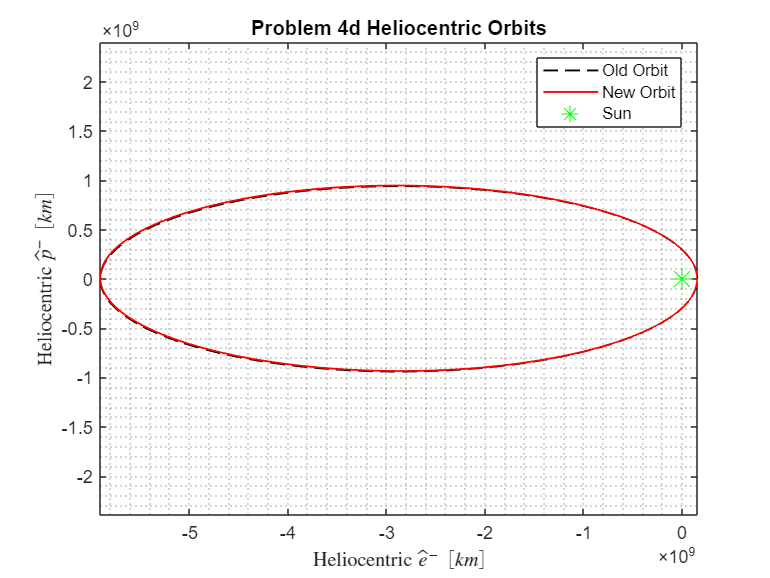

% True anomaly vector
ta_vec          = 0:.1:360;

% Initialize position vectors
r_P_minus_old   = zeros(2,length(ta_vec));  % Old orbit in original perifocal frame 
r_P_plus_new    = r_P_minus_old;            % New orbit in new perifocal frame
r_P_minus_new   = r_P_minus_old;            % New orbit in original perifocal frame

% Rotation matrix from new perifocal frame to original perifocal frame
Pminus_DCM_Pplus= [cosd(deltaAOP), -sind(deltaAOP);...
                   sind(deltaAOP), cosd(deltaAOP)];

% Semi-latus rectum of old heliocentric orbit
e_T             = 1 - rp_T/a_T;
% Semi-latus rectum of old heliocentric orbit
p_old           = a_T*(1 - e_T^2);

% Semi-latus rectum of new heliocentric orbit
p_new           = a_new*(1 - e_new^2);

for i = 1:length(ta_vec)

    % Calculate old orbit radii
    r_old               = p_old/(1 + e_T*cosd(ta_vec(i)));

    % Calculate new orbit radii
    r_new               = p_new/(1 + e_new*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R             = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                           sind(ta_vec(i)), cosd(ta_vec(i))];
    
    % Rotate old orbit poisition vector from orbit frame to perifocal frame
    r_P_minus_old(:,i)  = P_DCM_R*[r_old;0];

    % Rotate new orbit poisition vector from orbit frame to perifocal frame
    r_P_plus_new(:,i)   = P_DCM_R*[r_new;0];

    % Rotate new orbit position vector from new perifocal frame to original perifocal frame
    r_P_minus_new(:,i)  = Pminus_DCM_Pplus*r_P_plus_new(:,i);
        
end

figure
plot(r_P_minus_old(1,:), r_P_minus_old(2,:),'--k','LineWidth',1)
hold on
plot(r_P_minus_new(1,:), r_P_minus_new(2,:),'-r','LineWidth',1)
plot(0, 0,'g*','MarkerSize',12)
grid minor
xlabel('Heliocentric $\hat{e}^- \ [km]$', 'Interpreter','latex')
ylabel('Heliocentric $\hat{p}^- \ [km]$', 'Interpreter','latex')
axis equal
title('Problem 4d Heliocentric Orbits')
legend('Old Orbit','New Orbit','Sun')

% Change in FPA - original FPA is zero
deltaFPA    = gamma_plus;

% Calculate deltaV equivalent - law of cosines
dv_eq       = sqrt(v_plus_flyby^2 + va^2 - 2*va*v_plus_flyby*cosd(gamma_plus));
fprintf('The equivalent deltaV is %.4f km/s',dv_eq)

The equivalent deltaV is 0.0414 km/s


$$\Delta v_{eq}^2 = v^{+2} + v_a^2 - 2v_{a}v^+ + \cos{\Delta \gamma} \ \text{ - Law of cosines} \\
\\
\Delta v_{eq} = 0.041 \ [km/s]$$


% Flyby alpha
beta      = asind(sind(abs(deltaFPA))*v_plus_flyby/dv_eq);
fprintf('Alpha is %.3f deg',180 - beta)

Alpha is 90.322 deg


$$\frac{\Delta v_{eq}}{\sin{\Delta \gamma}} = \frac{v^+}{\sin{\beta}} \ \text{- Law of sines}\\
\alpha = 180 - \beta \\
\\
\alpha = 90.32 \ [deg]$$


**The spacecraft will be in an elliptical heliocentric orbit with respect to the sun, as observed in the plot above. It is possible to find a phase angle at departure so a spacecraft can encounter two objects. This can be done by knowing the time of flight of each transfer and determing the phase so that the first object will be in an appropriate position relative to the second object. If the timing is off, the spacecraft can be put in a parking orbit around the first object encountered, then wait for the correct phase to arise, as long as the first object is traveling faster than the second object.**